# MPL HW9

Steven Henderson

Two quantities x1 and x2 are measured, each with n samples. The covariance of the sample is,


$$\textrm{cov}\left(\textrm{x1},\textrm{x2}\right)=\frac{1}{n-1}\sum_i \left(\overset{-}{\textrm{x1}} -{\textrm{x1}}_i \right)\left(\overset{-}{\textrm{x2}} -{\textrm{x2}}_i \right)$$


where bars denote means. A simpler expression can be written,


$$\textrm{cov}\left(\textrm{x1},\textrm{x2}\right)=\frac{1}{n-1}\sum_i {\textrm{x1}}_i {\textrm{x2}}_i -\frac{n}{n-1}\overset{-}{\textrm{x1}} \overset{-}{\textrm{x2}}$$


% Import data
data = readmatrix("4xxx_grades.csv", 'Range', 'B2:C43') ;
HW = data(:, 1)' ;
FE = data(:, 2)' ;
% Function for finding covariance of two variables using equations above
function covariance = findCov(x1, x2)
    n = length(x1) ;
    covariance_sum = 0 ;
    for i = 1:length(x1)
        covariance_sum = covariance_sum + (mean(x1) - x1(i))*(mean(x2) - x2(i)) ;
    end
    covariance = 1/(n-1) * covariance_sum ;
end
% Find covariance using function above
cov_fractions = findCov(HW, FE) 

cov_fractions = 0.0552

% Use covariance function to find covariance matrix
CM = [findCov(HW, HW), findCov(HW, FE); findCov(FE, HW), findCov(FE, FE)]

CM =     0.0615    0.0552
    0.0552    0.0537


% Use matlab's covariance function to compare value which match with our
% values meaning our function is correct
matlab_CM = cov(HW, FE)

matlab_CM =     0.0615    0.0552
    0.0552    0.0537


% Function for finding the variance of a variable 
function variance = getVariance(x)
    variance_sum = 0 ;
    for i = 1:length(x)
        variance_sum = variance_sum + (x(i)-mean(x))^2 ;
    end
    variance = 1/length(x)*variance_sum ;
end
% Find variances of each variable
HW_variance = getVariance(HW) ;
final_variance = getVariance(FE) ;
% Find correlated variance using equation from book
correlated_variance = (1/4)*(HW_variance + final_variance + 2*findCov(HW, FE)) 

correlated_variance = 0.0557

% Find uncorrelated variance using equation from book
uncorrelated_variance = (1/4)*(HW_variance+final_variance)

uncorrelated_variance = 0.0281

% The correlated variance is higher that the uncorrelated variance, this is
% because there is an extra term that is summed over which makes sense.

**2.**

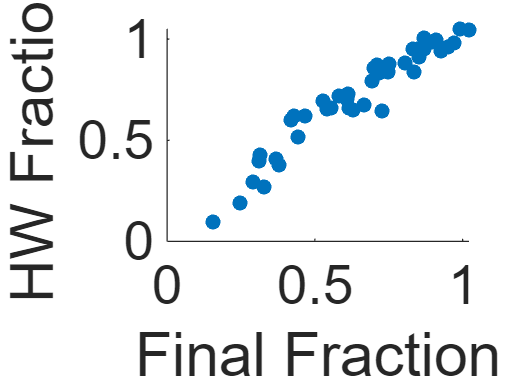

% Plot FE vs. HW
figure
scatter(FE, HW, 'filled')
set(gca, 'fontsize', 22)
xlabel('Final Fraction')
ylabel('HW Fraction')

% Data looks correlated so find correlations coefficient
function r = getCorCoeff(x1, x2)
% Function to find correlation coeff. using equation in HW and function to
% find the covariance from above
    r = (findCov(x1, x2))/sqrt(findCov(x1, x1)*findCov(x2, x2)) ;
end
getCorCoeff(HW, FE) % My found correlation coefficient

ans = 0.9606

[R, p] = corrcoef(HW, FE) % Find correlation coefficient using MatLab

R =     1.0000    0.9606
    0.9606    1.0000


p =     1.0000    0.0000
    0.0000    1.0000


% R is the correlation coeff. matrix in such for as
% r_x1x1 r_x1x2
% r_x2x1 r_x2x2
% The values found for x1x2 and x2x1 are the same and match the value I
% found using my function
% R is the corrcoef matrix for x1x1, x1x2, x2x1, x2x2
% p is probability values of each correlation
% The x1x2 values and x2x1 values show very low variance
p(1, 2)

ans = 7.6045e-24

p(2, 1)

ans = 7.6045e-24

% Meaning there is a high probabilty of correlation which matches our
% prediction